
ParentDir = "E:\YuLab\Work\GPS\Data";
TaskDir = uigetdir(ParentDir, "Choose task directionory");

ProgressClassFile = dir(TaskDir+"\*ProgressClass*.mat");
if length(ProgressClassFile)>1
    fprintf("More than one ProgressClass found");
    return;
end

load(fullfile(TaskDir, ProgressClassFile.name));

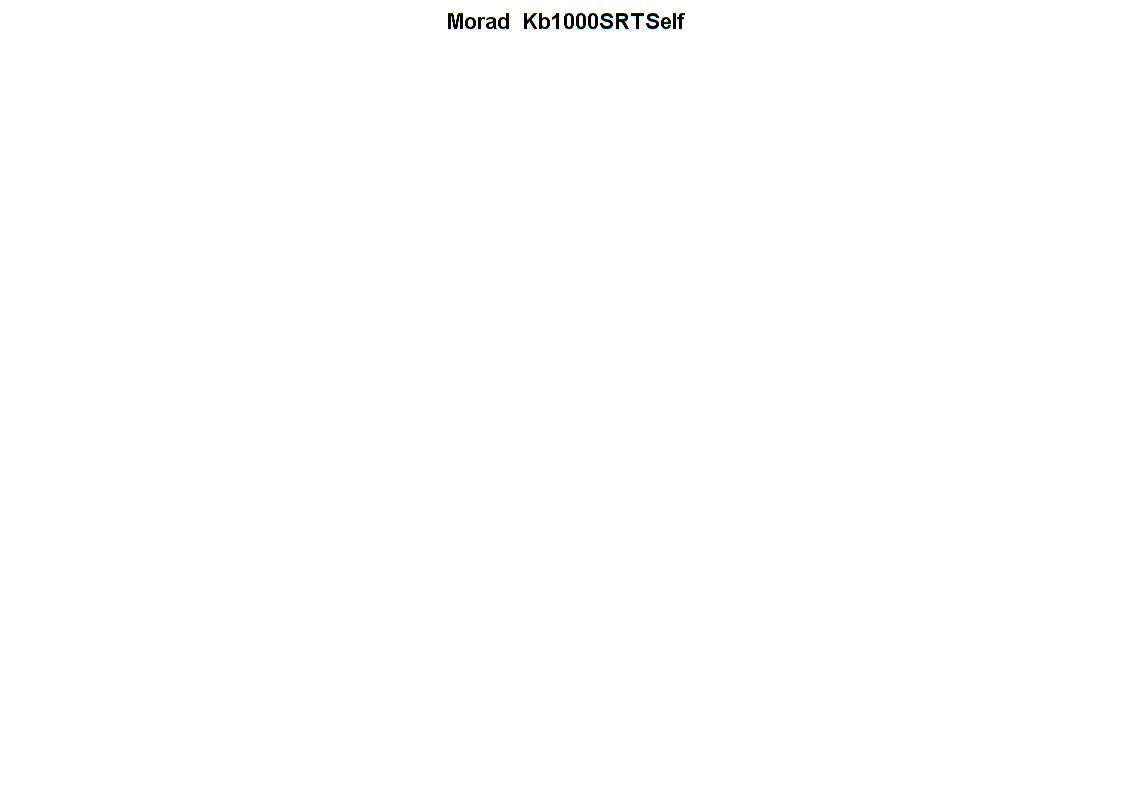

fig_kb = figure(51); clf(51);
set(fig_kb, 'Units', 'Centimeters', 'Position', [1 1 20 14], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_kb, 'units', 'normalized', 'position', [0.2 0.96 0.6 0.03],...
    'string', "Morad_Kb1000SRTSelf", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

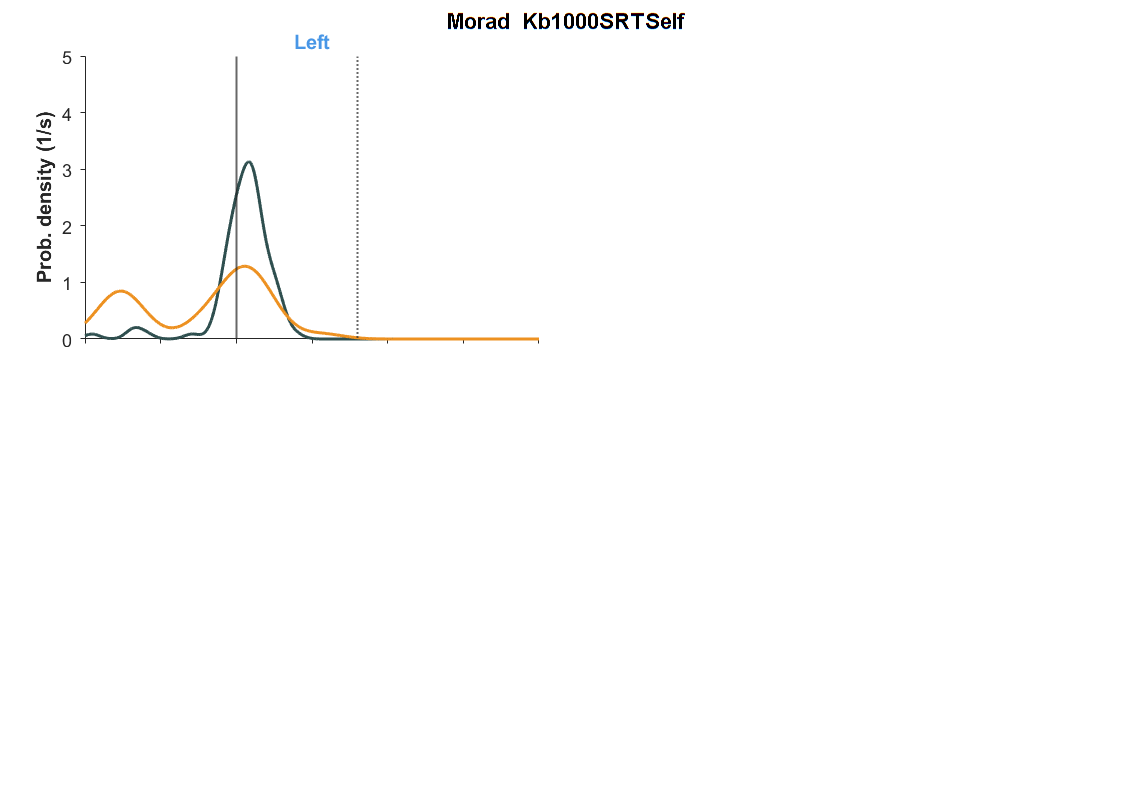


ax_pdf_l = axes;
set(ax_pdf_l, 'Units', 'Centimeters', 'Position', [1.5 8 8 5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

ax_pdf_l.Title.String = "Left";
ax_pdf_l.Title.FontWeight = "bold";
ax_pdf_l.Title.Color =  GPSColor.PortL;

xline(ax_pdf_l, 1, 'LineStyle', '-', 'LineWidth', 1);
xline(ax_pdf_l, 1.8, 'LineStyle', ':', 'LineWidth', 1);

ind_chemo = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Chemo"));
ind_control = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Control"));

hd_pdf_control_l = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portL & ind_control), obj.Bins.HoldDuration, 'Function', 'pdf');
plot(ax_pdf_l, obj.Bins.HoldDuration, hd_pdf_control_l, 'LineWidth', 1.5, 'Color', GPSColor.Control);

hd_pdf_chemo_l = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portL & ind_chemo), obj.Bins.HoldDuration, 'Function', 'pdf');
plot(ax_pdf_l, obj.Bins.HoldDuration, hd_pdf_chemo_l, 'LineWidth', 1.5, 'Color', GPSColor.Treat)

ax_pdf_l.YLabel.String = "Prob. density (1/s)";
ax_pdf_l.YLabel.FontWeight = "bold";

set(ax_pdf_l, 'YLim', [0 5], 'XTickLabel', []);

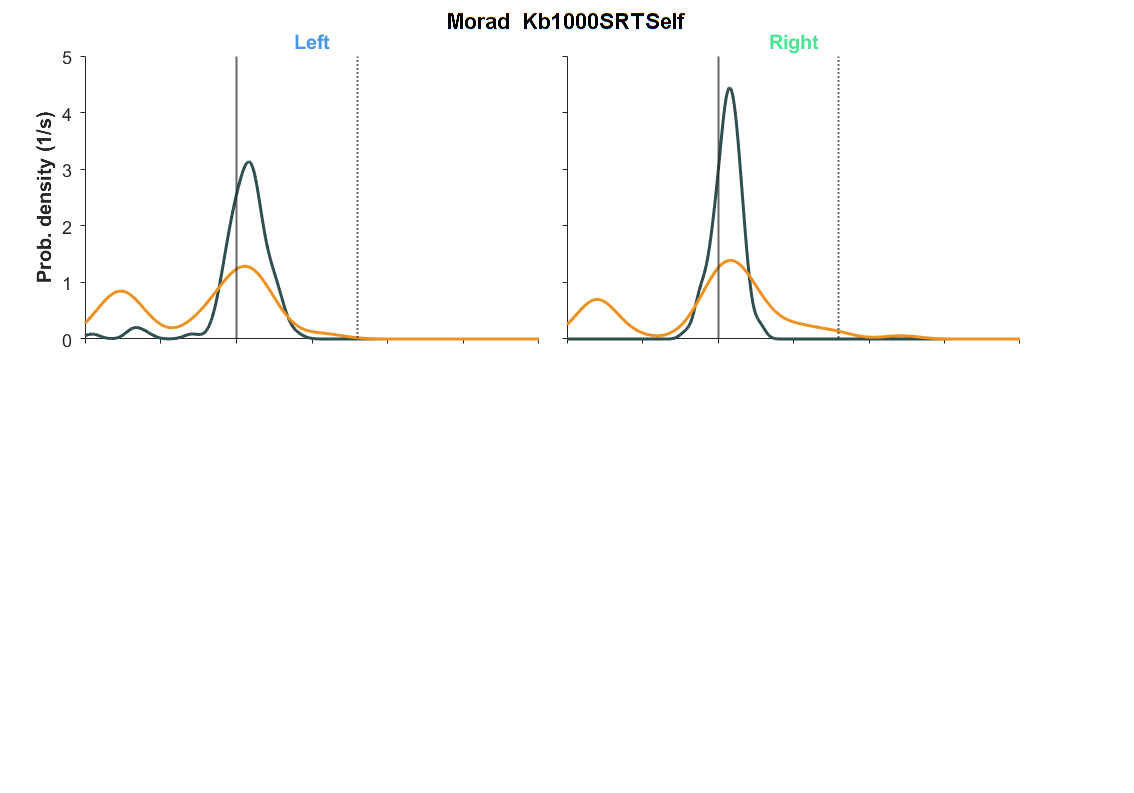

ax_pdf_r = axes;
set(ax_pdf_r, 'Units', 'Centimeters', 'Position', [10 8 8 5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

ax_pdf_r.Title.String = "Right";
ax_pdf_r.Title.FontWeight = "bold";
ax_pdf_r.Title.Color =  GPSColor.PortR;

xline(ax_pdf_r, 1, 'LineStyle', '-', 'LineWidth', 1);
xline(ax_pdf_r, 1.8, 'LineStyle', ':', 'LineWidth', 1);

ind_chemo = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Chemo"));
ind_control = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Control"));

hd_pdf_control_r = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portR & ind_control), obj.Bins.HoldDuration, 'Function', 'pdf');
plot(ax_pdf_r, obj.Bins.HoldDuration, hd_pdf_control_r, 'LineWidth', 1.5, 'Color', GPSColor.Control);

hd_pdf_chemo_r = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portR & ind_chemo), obj.Bins.HoldDuration, 'Function', 'pdf');
plot(ax_pdf_r, obj.Bins.HoldDuration, hd_pdf_chemo_r, 'LineWidth', 1.5, 'Color', GPSColor.Treat)

set(ax_pdf_r, 'YLim', [0 5], 'YTickLabel', [], 'XTickLabel', []);

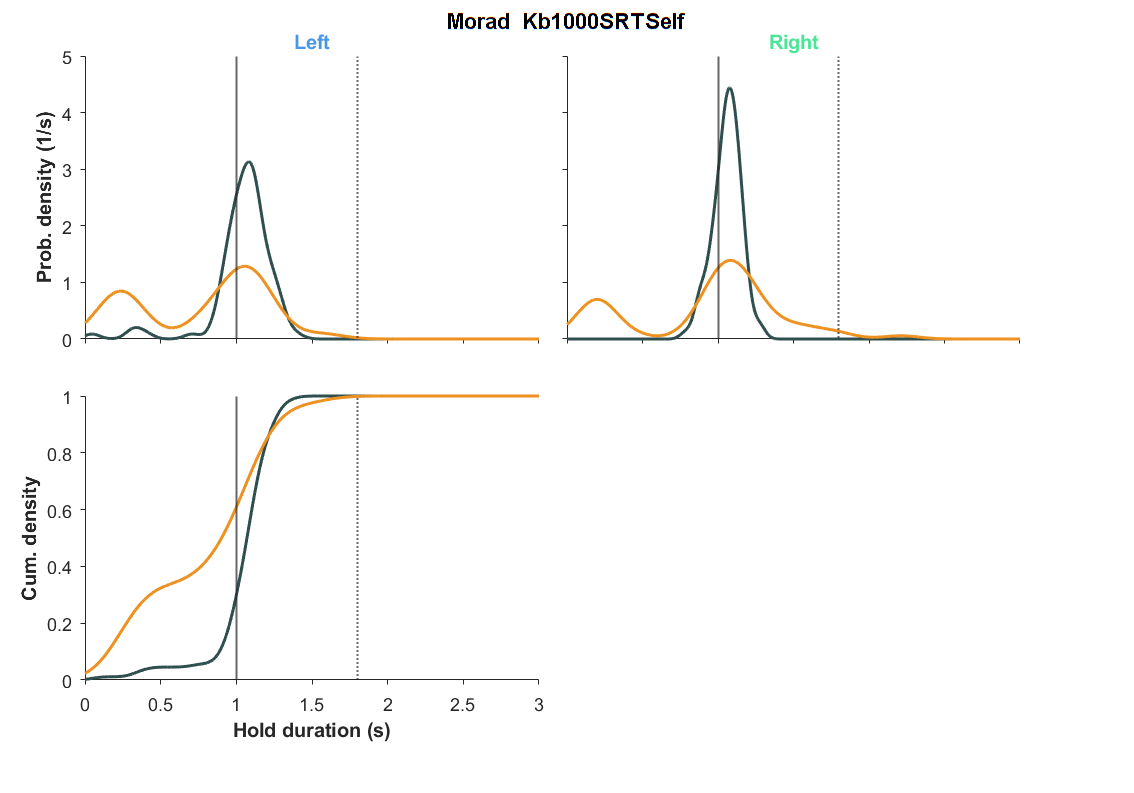

ax_cdf_l = axes;
set(ax_cdf_l, 'Units', 'Centimeters', 'Position', [1.5 2 8 5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_cdf_l, 1, 'LineStyle', '-', 'LineWidth', 1);
xline(ax_cdf_l, 1.8, 'LineStyle', ':', 'LineWidth', 1);

ind_chemo = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Chemo"));
ind_control = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Control"));

hd_cdf_control_l = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portL & ind_control), obj.Bins.HoldDuration, 'Function', 'cdf');
plot(ax_cdf_l, obj.Bins.HoldDuration, hd_cdf_control_l, 'LineWidth', 1.5, 'Color', GPSColor.Control);

hd_cdf_chemo_l = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portL & ind_chemo), obj.Bins.HoldDuration, 'Function', 'cdf');
plot(ax_cdf_l, obj.Bins.HoldDuration, hd_cdf_chemo_l, 'LineWidth', 1.5, 'Color', GPSColor.Treat)

ax_cdf_l.YLabel.String = "Cum. density";
ax_cdf_l.YLabel.FontWeight = "bold";
ax_cdf_l.XLabel.String = "Hold duration (s)";
ax_cdf_l.XLabel.FontWeight = "bold";

set(ax_cdf_l, 'YLim', [0 1]);

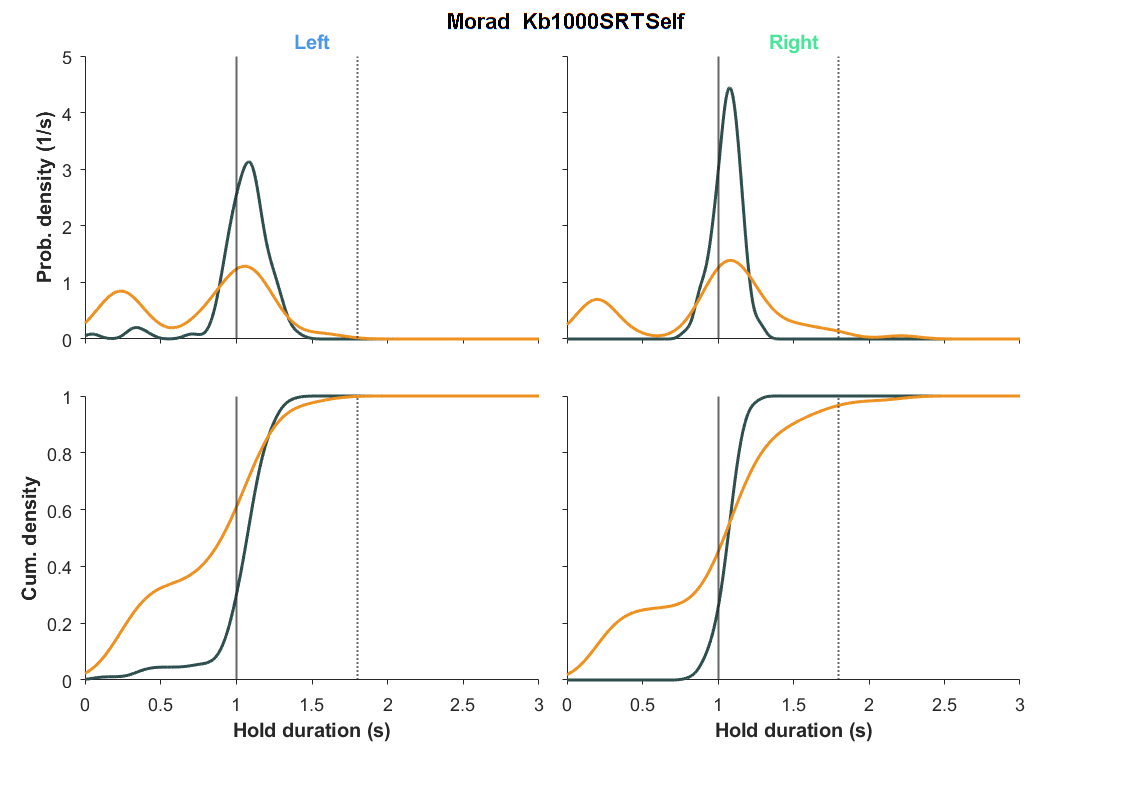

ax_cdf_r = axes;
set(ax_cdf_r, 'Units', 'Centimeters', 'Position', [10 2 8 5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_cdf_r, 1, 'LineStyle', '-', 'LineWidth', 1);
xline(ax_cdf_r, 1.8, 'LineStyle', ':', 'LineWidth', 1);

ind_chemo = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Chemo"));
ind_control = ismember(obj.BehavTable.SessionDate, obj.Sessions(obj.Label=="Control"));

hd_cdf_control_r = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portR & ind_control), obj.Bins.HoldDuration, 'Function', 'cdf');
plot(ax_cdf_r, obj.Bins.HoldDuration, hd_cdf_control_r, 'LineWidth', 1.5, 'Color', GPSColor.Control);

hd_cdf_chemo_r = ksdensity(obj.BehavTable.HoldDuration(obj.Ind.uncue & obj.Ind.portR & ind_chemo), obj.Bins.HoldDuration, 'Function', 'cdf');
plot(ax_cdf_r, obj.Bins.HoldDuration, hd_cdf_chemo_r, 'LineWidth', 1.5, 'Color', GPSColor.Treat)

ax_cdf_r.XLabel.String = "Hold duration (s)";
ax_cdf_r.XLabel.FontWeight = "bold";

set(ax_cdf_r, 'YLim', [0 1], 'YTickLabel', []);